# **CURRENTLY BROKEN!**

# **Automated Unit Tests**

Running ConsensusMAS.TestConsensus
Test 1. Fully Connected Network
Expect that average consensus is reached


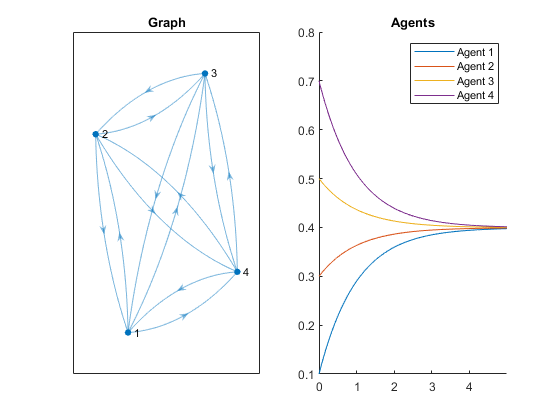

.
Test 2. One Root Node
Expect that root node consensus is reached


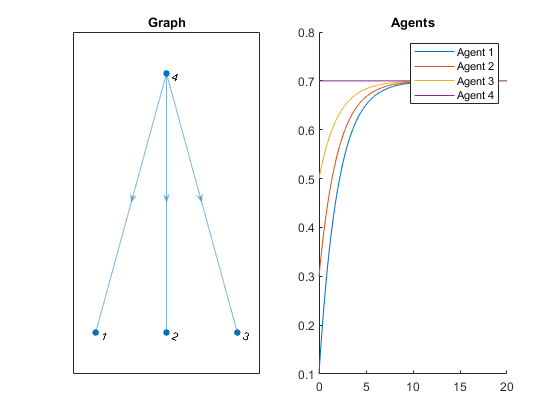

.
Test 3. Disconnected Network
Expect that consensus is not reached


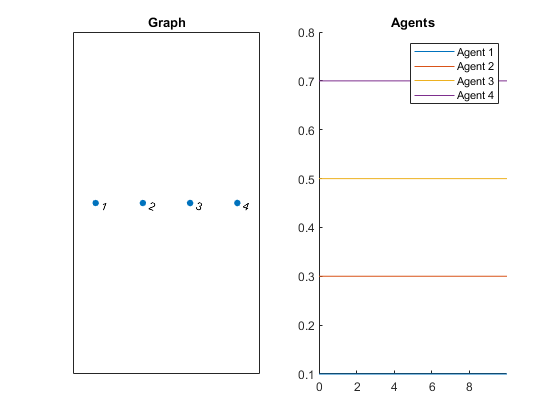

.
Done ConsensusMAS.TestConsensus
__________



import ConsensusMAS.*;
import ConsensusMAS.Utils.*
import matlab.unittest.selectors.HasParameter

suite = matlab.unittest.TestSuite.fromClass(?ConsensusMAS.TestConsensus);
selector = HasParameter('property', 'implementation', 'Name', 'FixedTrigger');
suite.selectIf(selector).run;

# **Manual Unit Tests**

**Discrete Time Consensus**

With $\tau_i =0\ldotp 2i-0\ldotp 1,\;\;\;\mathrm{for}\;i=1,2,\ldotp \ldotp \ldotp ,6$ and the following network, 

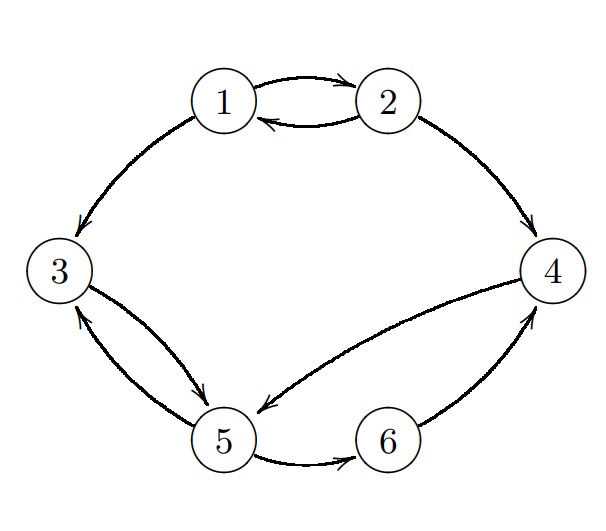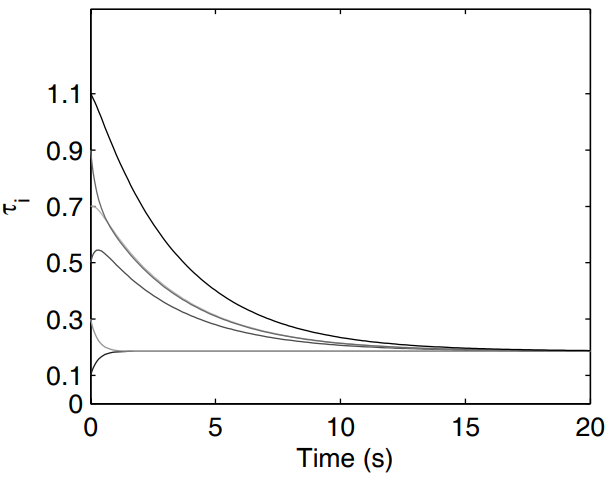

W. Ren and R. W. Beard, Distributed Consensus in Multi-vehicle Cooperative Control, London: Springer, 2008.  || page 37

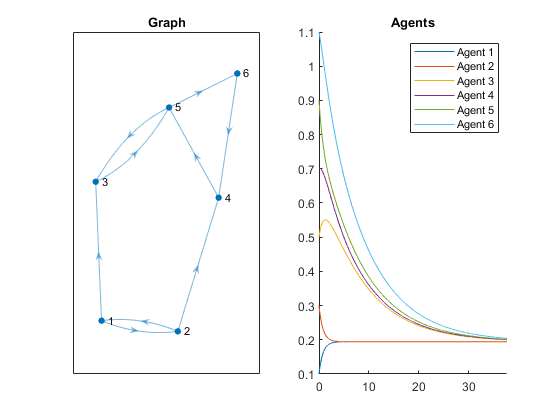

% TOY
import ConsensusMAS.*;
SIZE = 6;
A = [0 1.5 0 0 0 0; 2 0 0 0 0 0; 0.9 0 0 0 1.9 0; 
        0 1.2 0 0 0 1.3; 0 0 1.4 1.8 0 0; 0 0 0 0 0.7 0];
X0 = 0.2*(1:SIZE) - 0.1;

% Create the finite time network
network = Network(Implementations.FixedTrigger, A, X0);
network.Simulate('timestep', 1e-2, 'mintime', 20);
network.PlotGraphStates;